**Motor Calibration**

% data = [PASTE DATA HERE];
% speed_left = data(:,1)
% speed_right = data(:,2)
% delta_t = 0.02 % [s] time between samples 
% time = linspace(0,size(speed_left,1)*delta_t-delta_t,size(speed_left,1))
% time = time / 1000; % convert ms to s
% save("motor_calibration_data", "speed_left", "speed_right", "time")

syms tau K s
input_step_func = 300/s; % magnitude of motor input
motor_transfer_func = (K/tau) / (s + 1/tau);
velocity_transfer_func = input_step_func * motor_transfer_func

$$velocity\_transfer\_func = \frac{300\,K}{s\,\tau \,\left(s+\frac{1}{\tau }\right)}$$

velocity_over_time = ilaplace(velocity_transfer_func)

$$velocity\_over\_time = 300\,K-300\,K\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

load motor_calibration_data
velocity_left = velocity_fit(time, speed_left)

velocity_left =      General model:
     velocity_left(t) = 300*K*(1-exp(-t/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.002815  (0.002787, 0.002843)
       tau =     0.06612  (0.0576, 0.07464)

velocity_right = velocity_fit(time, speed_right)

velocity_right =      General model:
     velocity_right(t) = 300*K*(1-exp(-t/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.002985  (0.002956, 0.003014)
       tau =     0.06592  (0.05773, 0.07411)

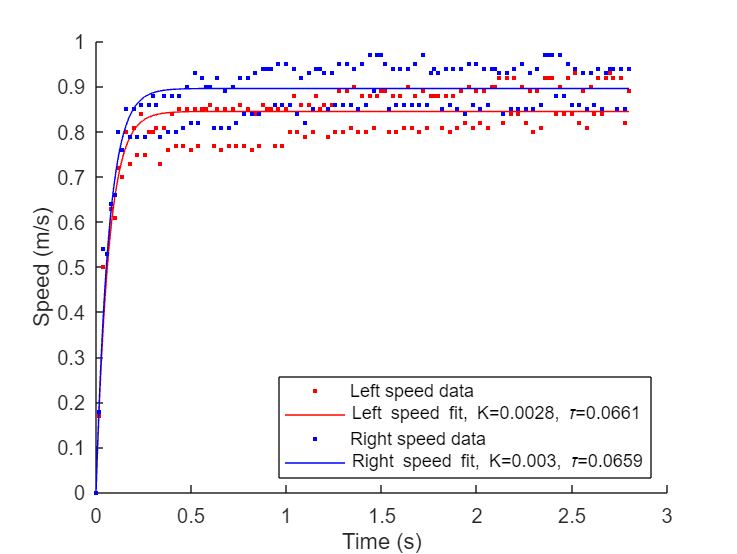


clf; hold on
plot(velocity_left, "r-", time, speed_left, "r.");
plot(velocity_right, "b-", time, speed_right, "b.");

xlabel("Time (s)")
ylabel("Speed (m/s)")
legend('Left speed data',...
       ['Left speed fit, K=', num2str(round(velocity_left.K, 4)), ', \tau=', num2str(round(velocity_left.tau, 4))],...
       'Right speed data',...
       ['Right speed fit, K=', num2str(round(velocity_right.K, 4)), ', \tau=', num2str(round(velocity_right.tau, 4))],...
       'Location', 'southeast')

**Gyro Calibration**

% gyro_angle = [PASTE DATA HERE];
% delta_t = 0.05 % [s] time between samples 
% time = linspace(0,size(gyro_angle,1)*delta_t-delta_t,size(gyro_angle,1))
% time = time / 1000; % convert ms to s
% save("gyro_calibration_data", "gyro_angle", "time")

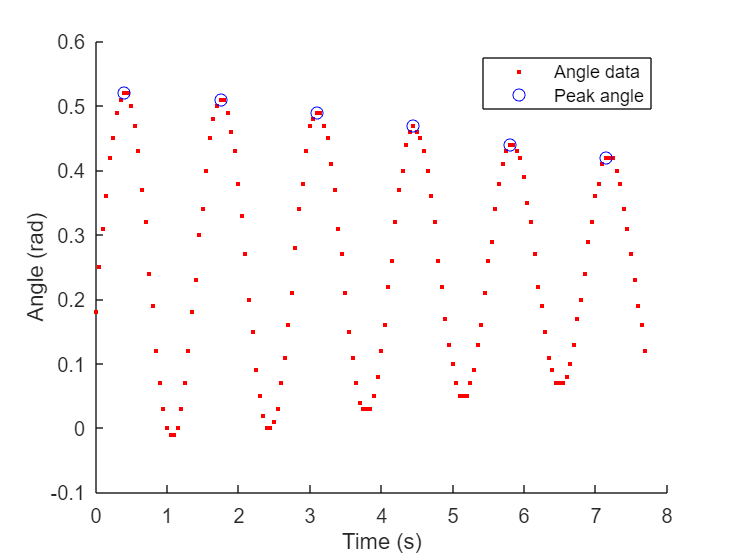

load gyro_calibration_data

clf; hold on
plot(time, gyro_angle, "r.") % could use rad2deg
xlabel('Time (s)')
ylabel('Angle (rad)')

[angle, t] = findpeaks(gyro_angle, time);
plot(t, angle, "bo");
legend(["Angle data","Peak angle"])


delta_t = t(2:end)-t(1:end-1); % time between peaks [s]
avg_period = mean(delta_t) % [s]

avg_period = 1.3500

frequency = 1/avg_period % [Hz]

frequency = 0.7407

natural_frequency = 2*pi*frequency % [rad/s]

natural_frequency = 4.6542

g = 9.81; % [m/s^2]
effective_length = g/natural_frequency^2 % [m]

effective_length = 0.4529

function [fitresult, gof] = velocity_fit(time, speed)
%  Data for 'velocity_fit' fit:
%      X Input: time
%      Y Output: speed
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness of fit info.

ft = fittype('300*K*(1-exp(-t/tau))', 'independent', 't', 'dependent', 'v');
opts = fitoptions('Method', 'NonlinearLeastSquares');
opts.StartPoint = [0.002 60/1000];
[fitresult, gof] = fit(time, speed, ft, opts);
end